# WorkSheet 6

## Problem 1

y = @(x1,x2,x3) [sin(x1-x2); (x3*exp(2.*x1)); (x1.^2+x2.^2+x3^2)];
y(1,2,3)

ans =    -0.8415
   22.1672
   14.0000


y= @(v) [sin(v(1)-v(2)), v(3).*exp(2.*v(1)), (v(1).^2) + (v(2).^2) + (v(3).^2)];
y([1;2;3])

ans =    -0.8415   22.1672   14.0000


## Problem 2

% See Scanned PDF

## Problem 3

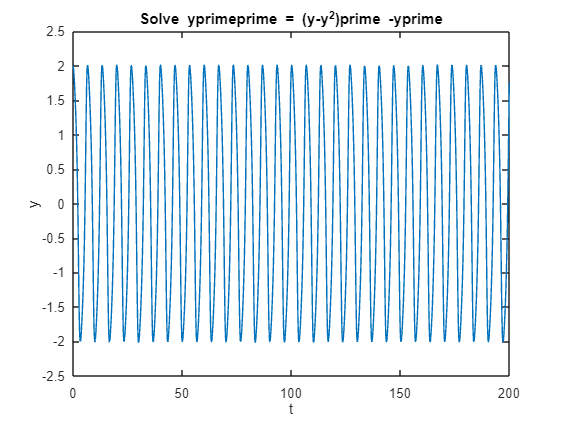

% 1) y1' = y2
%    y2' = (1-y^2)y2-y1
t0 = 0;
tf = 200;
tspan = linspace(t0,tf,1000);
y1_0 = 2; 
y2_0 = 0;
y0 = [y1_0,y2_0];
[t,Y] = ode45(@ode_setup_3, tspan, y0);
y = Y(:,1); 
yprime = Y(:,2);
figure
plot(t,y)
xlabel('t')
ylabel('y')
title('Solve yprimeprime = (y-y^2)prime -yprime')

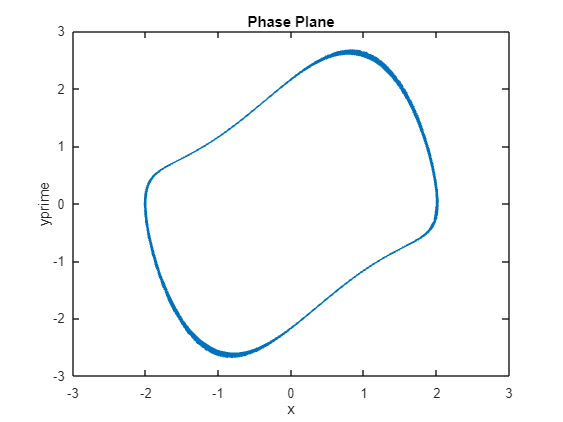

figure
plot(y,yprime);
xlabel('x');
ylabel('yprime');
title('Phase Plane')

## Problem 4

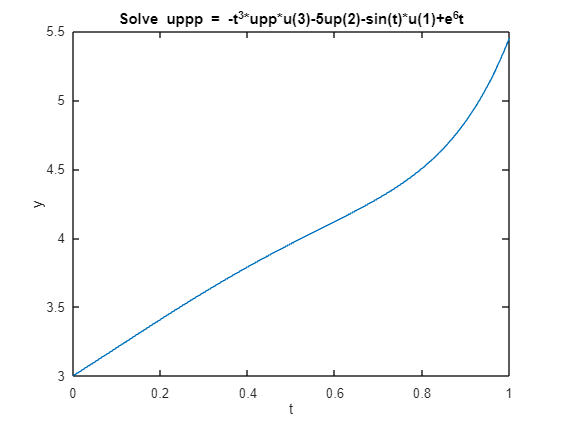

% 1) y1' = y2
%    y2' = y3
%    y3' = -t3y3-5y2-sin(t)*y1+e^6t
t0 = 0;
tf = 1;
tspand = linspace(t0,tf);
y1_0 = 3;
y2_0 = 2;
y3_0 = 1;
y0 = [y1_0,y2_0,y3_0];
[t,Y] = ode45(@ode_setup_4, tspand, y0);
y = Y(:,1); 
yprime = Y(:,2);
yprimeprime = Y(:,3);
figure 
plot(t,y)
xlabel('t')
ylabel('y')
% p = prime
title('Solve uppp = -t^3*upp*u(3)-5up(2)-sin(t)*u(1)+e^6t')

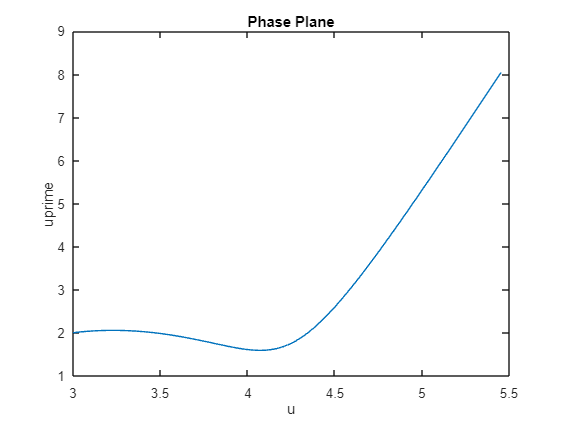

figure 
plot(y,yprime)
xlabel('u')
ylabel('uprime')
title('Phase Plane')